%B11102112 李家睿

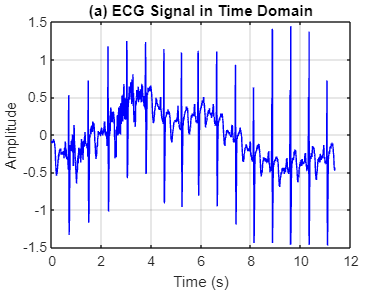

% lab8_ecg_analysis_windowed_normalized_stem.m
% ECG analysis with Hamming window visualization and HR comparisons
clear; close all; clc;

%% Load data
load('wecg.mat');      % wecg: 2048×1 ECG vector
samplerate = 180;      % Sampling frequency [Hz]
Ts = 1/samplerate;     % Sampling interval [s]
N = length(wecg);      % Number of samples (2048)
t = (0:N-1) * Ts;      % Time vector [s]

%% FFT parameters
nfft   = 2^nextpow2(N);                               % Zero-padded FFT length
faxis  = samplerate/2 * linspace(0,1,nfft/2+1);        % Frequency axis [Hz]

%% (a) Time-domain ECG
figure;
plot(t, wecg, 'b');
xlabel('Time (s)');
ylabel('Amplitude');
title('(a) ECG Signal in Time Domain');
grid on;

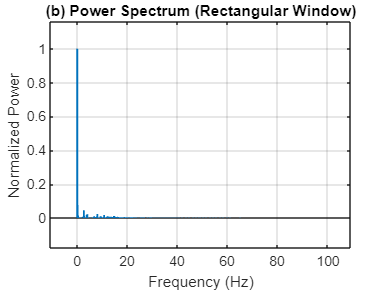


%% (b) FFT, power spectrum (rectangular window, normalized + zero-padded)
Y   = fft(wecg, nfft);
PS  = abs(Y).^2;                 % Power spectrum
PS  = PS(1:nfft/2+1);            % Keep one side
PS(2:end-1) = 2*PS(2:end-1);     % Double non-DC/non-Nyquist bins
PS  = PS / max(PS);              % normalize to 1

figure;
stem(faxis, PS, 'Marker','none','LineWidth',1.2);
xlim([0 samplerate/2]);
xlabel('Frequency (Hz)');
ylabel('Normalized Power');
title('(b) Power Spectrum (Rectangular Window)');
grid on;

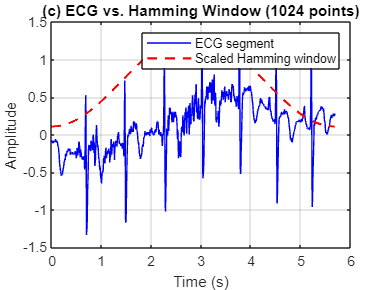


[~, idx_unwin] = max(PS);
f_unwin  = faxis(idx_unwin);
hr_unwin = f_unwin * 60;  % bpm

%% (c) FFT with 1024-pt Hamming window
L      = 1024;
w      = hamming(L);
w_full = [w; zeros(N-L,1)];     % Zero-pad window to full length

% Visualize window overlay
tL       = t(1:L);
w_scaled = w * max(abs(wecg(1:L)));

figure;
plot(tL, wecg(1:L), 'b');
hold on;
plot(tL, w_scaled, 'r--','LineWidth',1.5);
xlabel('Time (s)');
ylabel('Amplitude');
legend('ECG segment','Scaled Hamming window');
title('(c) ECG vs. Hamming Window (1024 points)');
grid on;

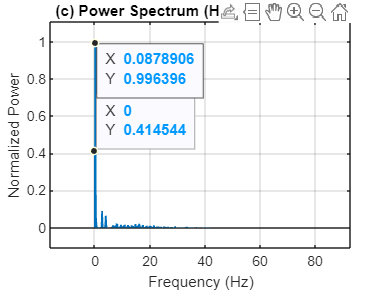


% Apply window & compute FFT
xw  = wecg .* w_full;
Yw  = fft(xw, nfft);
PSw = abs(Yw).^2;
PSw = PSw(1:nfft/2+1);
PSw(2:end-1) = 2*PSw(2:end-1);
PSw = PSw / max(PSw);           % normalize to 1

figure;
stem(faxis, PSw, 'Marker','none','LineWidth',1.2);
xlim([0 samplerate/2]);
xlabel('Frequency (Hz)');
ylabel('Normalized Power');
title('(c) Power Spectrum (Hamming Window)');
grid on;

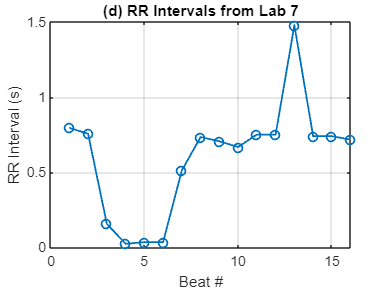


[~, idx_win] = max(PSw);
f_win  = faxis(idx_win);
hr_win = f_win * 60;  % bpm

%% (d) RR-interval method (with DC offset removal)
dc_offset      = mean(wecg(wecg < 0));
wecg_detrended = wecg - dc_offset;

[peaks, locs] = findpeaks(wecg_detrended, 'MinPeakHeight', 1);
RR_intervals  = diff(locs) * Ts;
avgRR         = mean(RR_intervals);
hr_rr         = 60 / avgRR;  % bpm

figure;
plot(RR_intervals, '-o', 'LineWidth', 1.2);
xlabel('Beat #');
ylabel('RR Interval (s)');
title('(d) RR Intervals from Lab 7');
grid on;


%% Summary of HR estimates
fprintf('\nHeart-rate estimates:\n');


Heart-rate estimates:


fprintf('  FFT (no window):        %5.1f bpm (peak at %.2f Hz)\n', hr_unwin, f_unwin);

  FFT (no window):          5.3 bpm (peak at 0.09 Hz)


fprintf('  FFT (1,024-pt Hamming): %5.1f bpm (peak at %.2f Hz)\n', hr_win, f_win);

  FFT (1,024-pt Hamming):  10.5 bpm (peak at 0.18 Hz)


fprintf('  RR-interval method:     %5.1f bpm (avgRR = %.3f s)\n\n', hr_rr, avgRR);

  RR-interval method:     100.2 bpm (avgRR = 0.599 s)



%Today is the first lab after the midterm exam, 
%the Lab is much difficult than those before the 
%midterm, and there are many formula that I had not seen before,
%which require lots of time to understand the process.